## Análisis cinemático

clear
clc



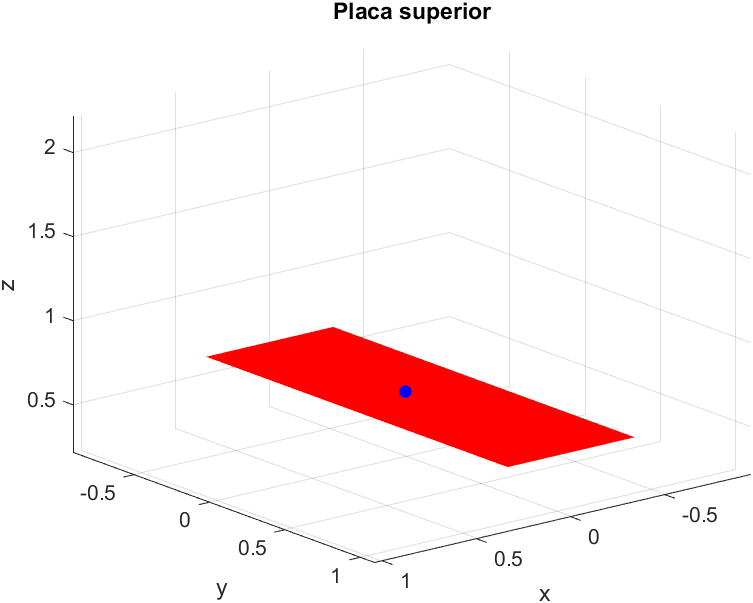



b=2.3;
h=0.675;

syms beta(t) theta(t) x y z 

Pi=[x y z];


### Cinemática actuador Xa

syms  vmaxXa tfXa Xa(t)
assume (tfXa>0);

g=9.81;
acXa=0.5*g;
x=0.3;

f1=acXa==2*vmaxXa/tfXa;
f2=x==vmaxXa.*tfXa/2;

[vmaxXa,tfXa]=solve([f1 f2],[vmaxXa tfXa])

$$vmaxXa = \frac{3\,\sqrt{1635}}{100}$$

$$tfXa = \frac{4\,\sqrt{1635}}{327}$$


Xa(t)=piecewise(t<0.5*tfXa,0.5*acXa*t^2,t>=0.5*tfXa,vmaxXa*t-0.5*acXa*(t-0.5*tfXa)^2-vmaxXa*tfXa/4)

$$Xa(t) = \left\{ \begin{array}{cl} \frac{981\,t^{2}}{400} & \text{ if }327\,t^{2}-20<0\\ \frac{3\,\sqrt{1635}\,t}{100}-\frac{981\,{\left(t-\frac{2\,\sqrt{1635}}{327}\right)}^{2}}{400}-\frac{3}{20} & \text{ if }0\leq 327\,t^{2}-20 \end{array}\right.$$

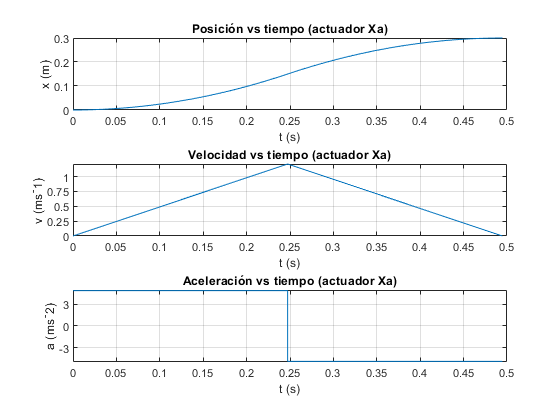

figure()
subplot(3,1,1)
fplot(Xa,[0 double(tfXa)])
grid on
xlabel('t (s)')
ylabel('x (m)')
yticks(0:0.1:0.3)
title('Posición vs tiempo (actuador Xa)')
subplot(3,1,2)
fplot(diff(Xa),[0 double(tfXa)])
grid on
xlabel('t (s)')
ylabel('v (ms^-1)')
yticks(0:0.25:1.25)
title('Velocidad vs tiempo (actuador Xa)')
subplot(3,1,3)
fplot(diff(diff(Xa)),[0 double(tfXa)])
grid on
xlabel('t (s)')
ylabel('a (ms^-2)')
yticks(-6:3:6)
title('Aceleración vs tiempo (actuador Xa)')

### Cinemática actuador Za

syms  vmaxZa tfZa Za(t)
assume (tfZa>0);

g=9.81;
acXa=0.5*g;
x=0.2;
f1=acXa==2*vmaxZa/tfZa;
f2=x==vmaxZa.*tfZa/2;

[vmaxZa,tfZa]=solve([f1 f2],[vmaxZa tfZa])

$$vmaxZa = \frac{3\,\sqrt{1090}}{100}$$

$$tfZa = \frac{4\,\sqrt{1090}}{327}$$


Za(t)=piecewise(t<0.5*tfZa,0.5*acXa*t^2,t>=0.5*tfZa,vmaxZa*t-0.5*acXa*(t-0.5*tfZa)^2-vmaxZa*tfZa/4)

$$Za(t) = \left\{ \begin{array}{cl} \frac{981\,t^{2}}{400} & \text{ if }981\,t^{2}-40<0\\ \frac{3\,\sqrt{1090}\,t}{100}-\frac{981\,{\left(t-\frac{2\,\sqrt{1090}}{327}\right)}^{2}}{400}-\frac{1}{10} & \text{ if }0\leq 981\,t^{2}-40 \end{array}\right.$$

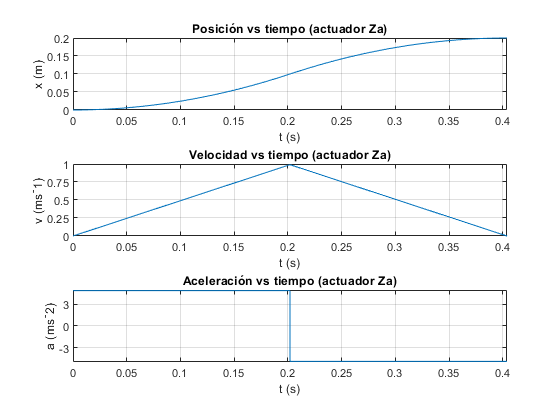

figure()
subplot(3,1,1)
fplot(Za,[0 double(tfZa)])
grid on
xlabel('t (s)')
ylabel('x (m)')
yticks(0:0.05:0.2)
title('Posición vs tiempo (actuador Za)')
subplot(3,1,2)
fplot(diff(Za),[0 double(tfZa)])
grid on
xlabel('t (s)')
ylabel('v (ms^-1)')
yticks(0:0.25:1)
title('Velocidad vs tiempo (actuador Za)')
subplot(3,1,3)
fplot(diff(diff(Za)),[0 double(tfZa)])
grid on
xlabel('t (s)')
ylabel('a (ms^-2)')
yticks(-6:3:6)
title('Aceleración vs tiempo (actuador Za)')

Ecuaciones generales


Wbeta(t)=[beta(t) 0 0];
Wtheta(t)=[0 theta(t) 0];
Wtotal(t)=Wbeta(t)+Wtheta(t);

VelocidadPO(t)=cross(diff(Wtotal(t)),Pi);
aceleracionAngular(t)=diff(diff(Wtotal(t)));

AceleracionPO(t)=cross(aceleracionAngular(t),Pi)+cross(Wtotal(t),VelocidadPO(t));


Velocidad(t)=VelocidadPO(t)+diff([Xa(t) 0 Za(t)])
Aceleracion(t)=AceleracionPO(t)+diff(diff([Xa(t) 0 Za(t)]))



function [x1] = delta(t)
    x1= (t==0);
end

function [x1] = escalon(t)
    x1= (t>=0);
end

function [x1] = rampa(t)
    x1= t.*(t>=0);
end

